# FlowerDemo.m is a demonstration script

Script file to demonstrate a few of the processing algorithms we have so far.

% Read the image

close all; clear; clc;

fprintf('Reading the image and changing the color space\n');

%raw_photos = dir

F =imread('P442F1.JPG');

fprintf('done');


% transform

figure(1)
imshow(F)
title('Sample Image')
lab_he=rgb2lab(F);

% Transform the RGB values to LAB scales (more grey tones)

ab=double(lab_he(:,:,2:3));
nrows=size(ab,1);
ncols=size(ab,2);
ab=reshape(ab,nrows*ncols,2);

clear F lab_he 
% reshape to be just the L,A colors as a p by 2 array

whos


## Split the flower using kmeans clustering on the colors.

fprintf('Kmeans clustering\n');

nColors=3;

initial_centers = [ -2 2 ;-9 60.5, ;  31 33 ] ;
[cluster_idx,~]= kmeans(ab,nColors,'distance','sqEuclidean','Start',initial_centers);

% Show the results:
pixel_labels=reshape(cluster_idx,nrows,ncols);
figure(2)
imshow(pixel_labels,[]);
title('Image Labeled by Cluster Index');

clear initial_centers;


## can we get just the spots?

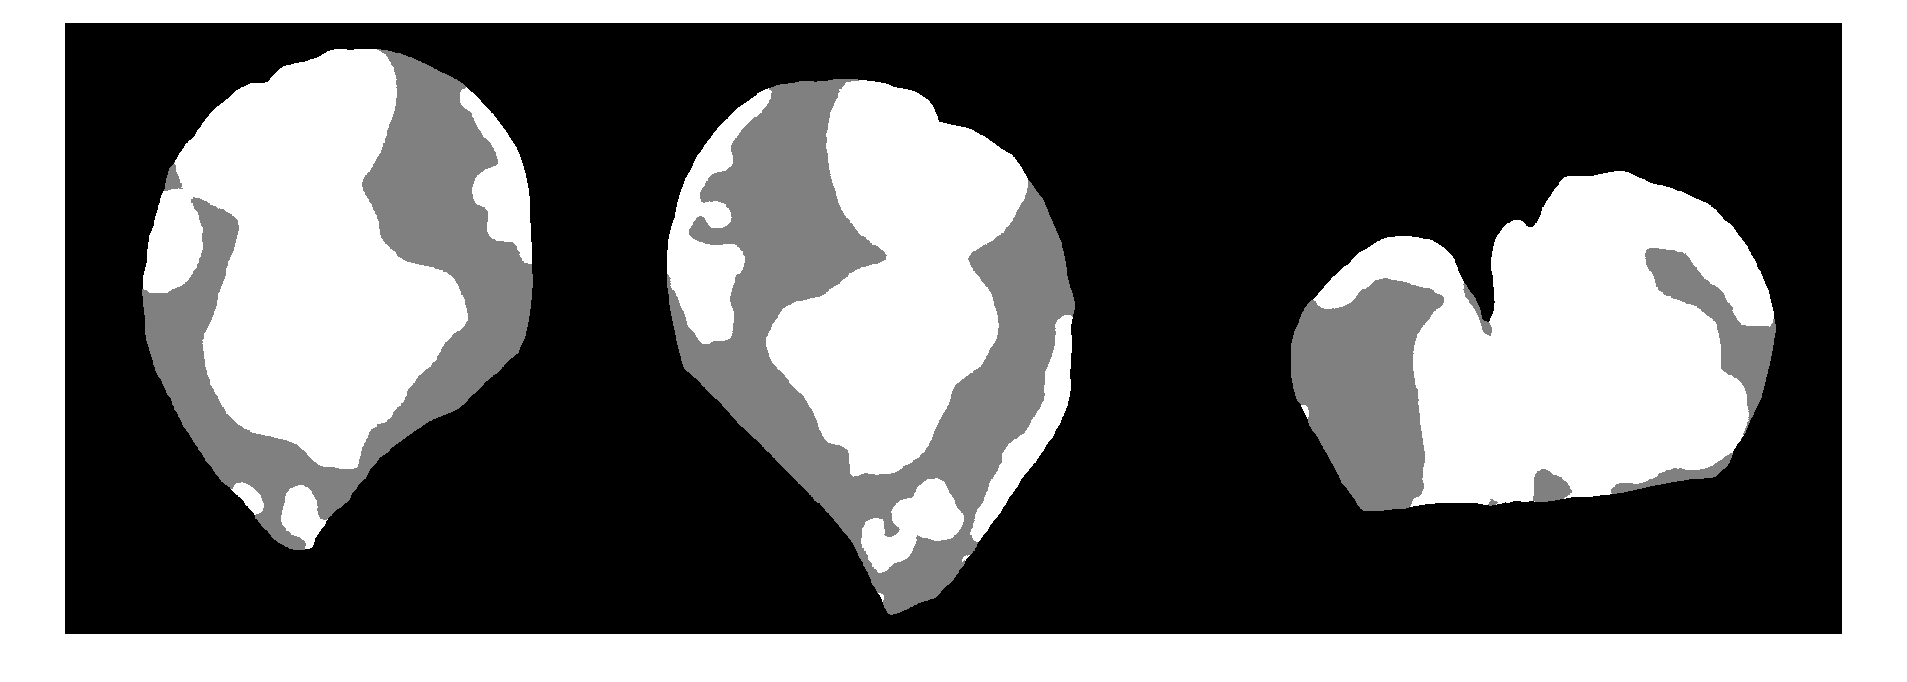

aa = pixel_labels;

%unique(aa)

%% at least with this photo, 
%% 1 = tape background
%% 2 = petal background 
%% 3 = spots

%% so to get the petal shape outline:
aa(aa == 1) = 0; %% 1 = tape background
aa(aa == 2) = 1; %% 2 = petal background/shape
aa(aa == 3) = 1; %% 3 = spots

imshow(pixel_labels,[]);

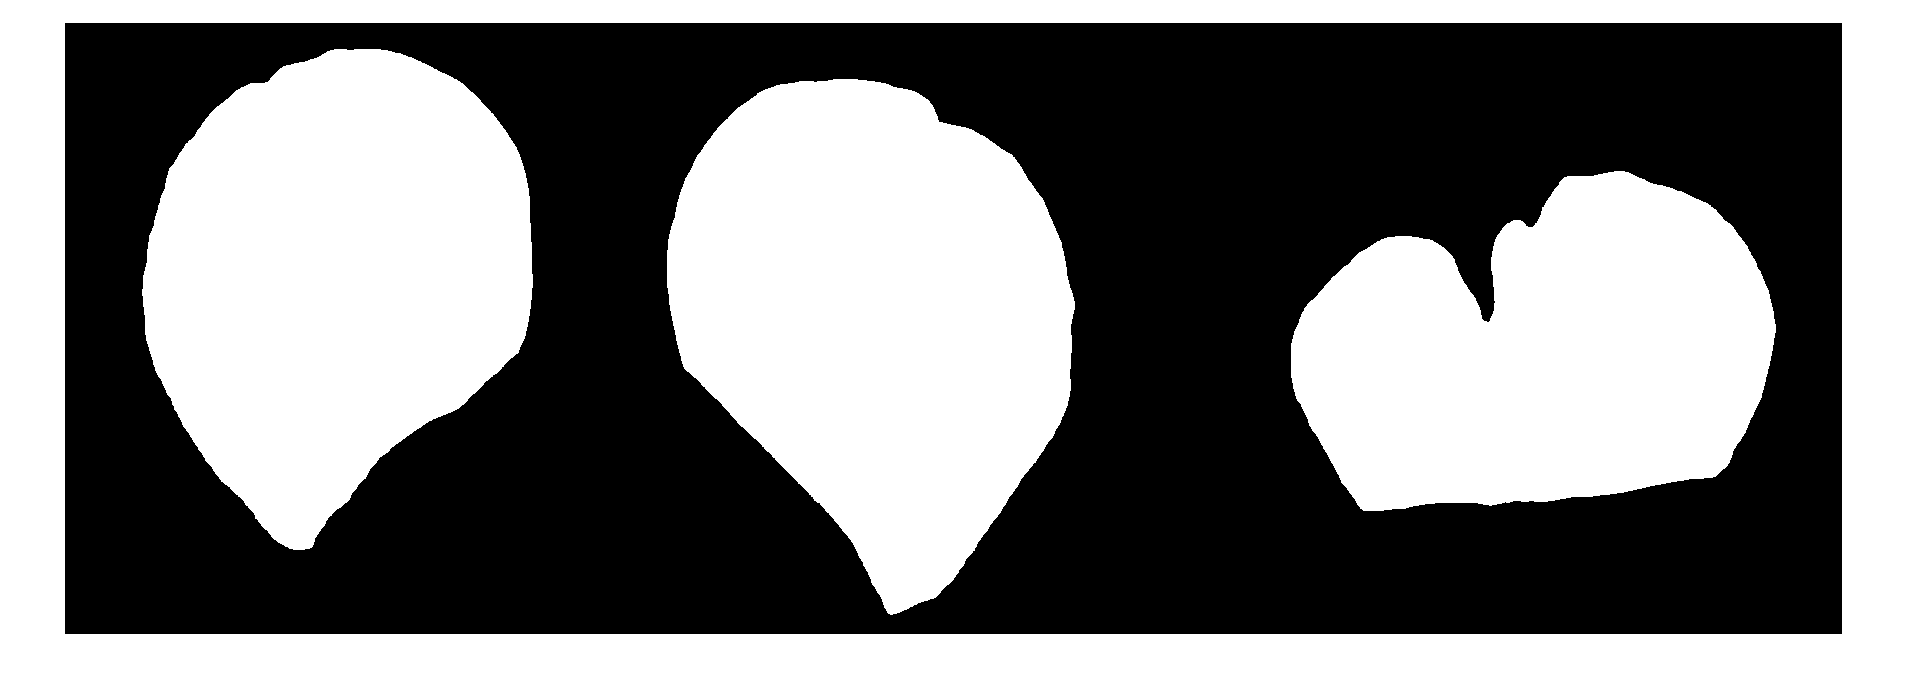

imshow(aa,[]);

imwrite(aa,'test_outline3.png') %% works

%% to get the spots:
aa = pixel_labels;
aa(aa == 1) = 0; %% tape background
aa(aa == 2) = 0; %% petal background/shape 
aa(aa == 3) = 1; %% spots

imshow(pixel_labels,[]);

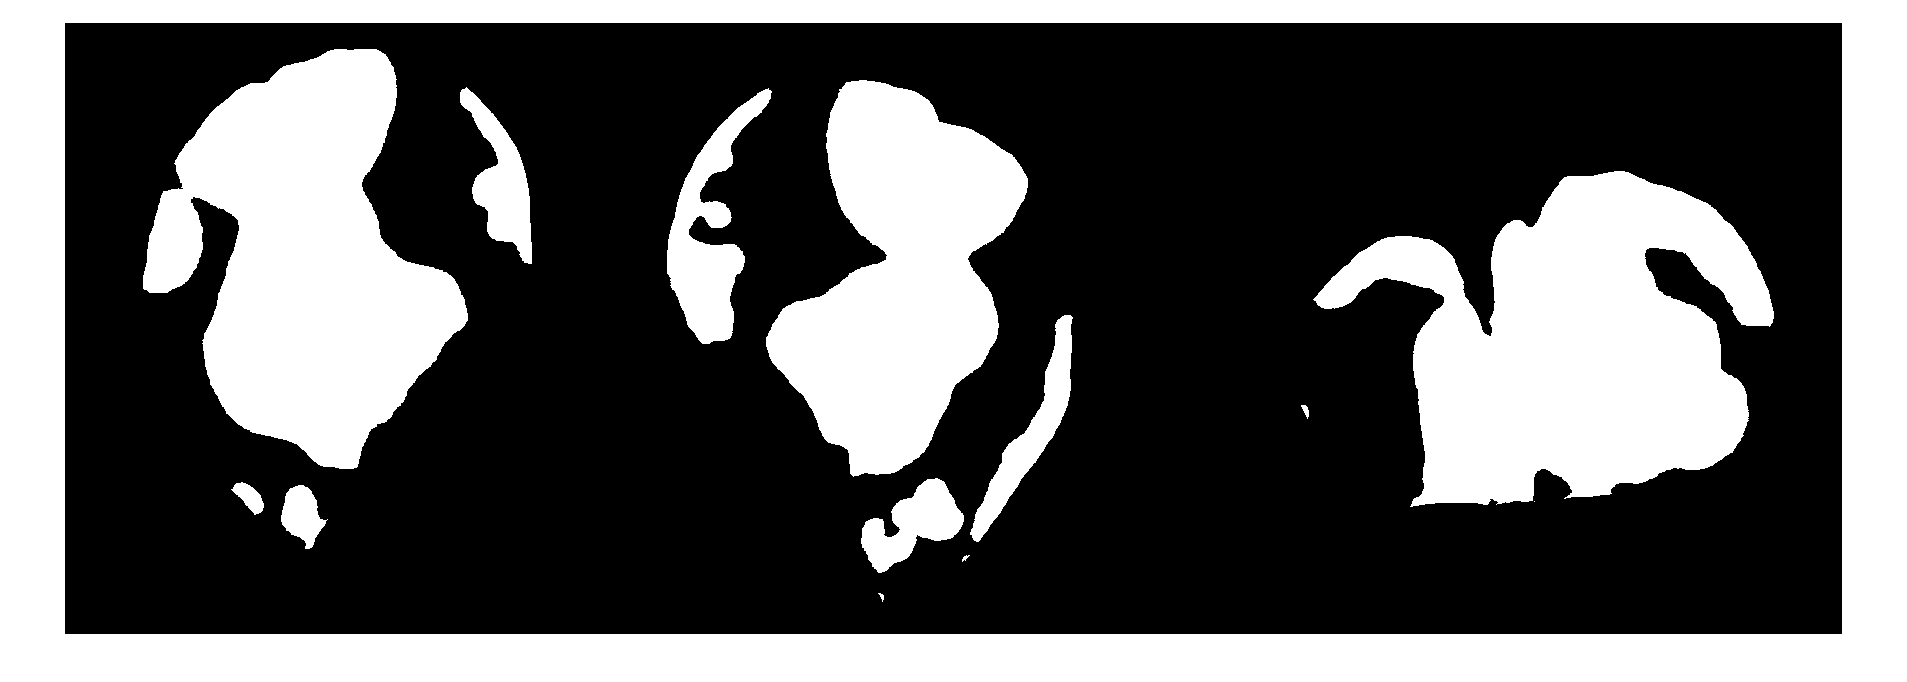

imshow(aa,[]);

imwrite(aa,'test_spots3.png') 

## Find the indices for the left, mid and right petals for further processing:

fprintf('Splitting the leaves\n');

% We assume the background color index can be pulled off the first pixel:
    background = pixel_labels(1);

    % Find the positions of each petal:
    temp=(pixel_labels~=background); % temp is a logical array; 0=background, 1=petal (or not background)
    index=find(temp);   % "index" is a linear indexing of the 1's in temp- Next line converts it to (x,y)
    [y, x] = ind2sub(size(pixel_labels),index); 

    % pos is the position index (1,2,3), and pos_cluster_center returns the
    % centers of the three leaves.
    [pos, pos_cluster_center] = kmeans([y, x],3,'distance','sqEuclidean','Replicates',3);

    % "color" is a vector that has size equal to the number of pixels in the
    % leaves, and whose value is the original color index (2 or 3 for red
    % or yellow)
    %
    % We note that "color", "index", "x", "y", "pos" all have the same size- 
    %  Which is the number of pixels that are making up the leaves.

    color=cluster_idx(cluster_idx~=background);  

    loc_color = [x, y, pos, color]; % pixel row, column, then position index, then color index.

    sortx = sortrows(loc_color);  % Default sort is on first column (x-coordinate)
    
    % "left" petals = "upper left" or "dorsal left" , methinks -dan 
    left = sortx(50,3);           % Ad-hoc assignment for "left"
    left_petal = loc_color(pos==left,:);

    % "Right" petals are what we would call "bottom" or "ventral"
    right = sortx(end-50,3);
    right_petal = loc_color(pos==right,:);

    % "mid" petals = "upper right" or "dorsal right" in real life
    mid = 6 - left - right;
    mid_petal = loc_color(pos==mid,:);
    
    %% looking at these, it seems like the upperLeft, or doug's "left" petal
    %% got a location index of 2. upperRight or dougs "mid" location index = 3,
    %% and bottom/"right" location index = 1
    
    % Save the information in "data"
    Petals.left.data = left_petal;
    Petals.right.data = right_petal;
    Petals.mid.data = mid_petal;

    clear background circle_idx color index loc_color pos sortx;
    
    fprintf('done')
    
    

    whos

  Name                          Size                 Bytes  Class      Attributes

  P442F1_petals                 1x1               13092992  struct               
  Petals                        1x1               13092992  struct               
  Temp                        611x1777             8685976  double               
  aa                          611x1777             8685976  double               
  ab                      1085747x2               17371952  double               
  ans                           3x1                     24  double               
  cluster_idx             1085747x1                8685976  double               
  i                             1x1                      8  double               
  left                          1x1                      8  double               
  left_petal               138213x4                4422816  double               
  mid                           1x1                      8  double               
  mid_petal    

    Petals.left.data

ans =     78   267     3     2
    78   268     3     2
    78   269     3     2
    78   270     3     2
    78   271     3     2
    78   272     3     2
    78   273     3     2
    79   253     3     3
    79   254     3     3
    79   255     3     3


    %% how do we save out a data object?
    
    P442F1_petals = Petals

P442F1_petals = struct with fields:
     left: [1×1 struct]
    right: [1×1 struct]
      mid: [1×1 struct]


    save('P442F1_petals.mat','Petals')
    

    
    %% can we get these split up, individual petals as their 
    %% own image files?
    
    unique(Petals.left.data(:,4))

ans =      2
     3


    
    size(Petals.left.data)

ans =       138213           4


    
    %imshow(Petals.left.data)
    
    
    
    
    

## Graphically show what was just computed:

   figure(3)
 
   Temp=double(temp);  % temp was a logical array, convert to numerical
   [aa,~]=size(left_petal);
   for i=1:aa
       Temp(left_petal(i,2),left_petal(i,1))=2;
   end
   [aa,~]=size(mid_petal);
   for i=1:aa
       Temp(mid_petal(i,2),mid_petal(i,1))=3;
   end
   [aa,~]=size(right_petal);
   for i=1:aa
       Temp(right_petal(i,2),right_petal(i,1))=4;
   end
   imshow(Temp,[0,4]);
   title('Sorted the leaves by position as shown by color');
   

   %clear temp Temp
   

  %Temp
  
  imshow(temp,[0,4])
   %size(left_petal)

## Back to the code:

    Petals.left.prop_red=propred(left_petal(:,4));
    Petals.right.prop_red=propred(right_petal(:,4));
    Petals.mid.prop_red=propred(mid_petal(:,4));

## Trial for "Clumpiness":

Curves are measuring distance from center vs proportion of red:

## Clumpiness

    z_left=sqrt(((left_petal(:,1)-pos_cluster_center(left,2)).^2 + (left_petal(:,2)-pos_cluster_center(left,1))).^2);
    circleidx_left=linspace(min(z_left),max(z_left),200);
    colorz_left=[left_petal(:,4),z_left];
    
    for r=1:200

        circle_left=(colorz_left(z_left<=circleidx_left(r),:));
        prpr_left = propred(circle_left(:,1));
        circlereds_left(r) = prpr_left;
        rs_left(r)= r;
        
    end
    
    z_mid=sqrt(((mid_petal(:,1)-pos_cluster_center(mid,2)).^2 + (mid_petal(:,2)-pos_cluster_center(mid,1))).^2);
    circleidx_mid=linspace(min(z_mid),max(z_mid),200);
    colorz_mid=[mid_petal(:,4),z_mid];
    
    for r=1:200

        circle_mid=(colorz_mid(z_mid<=circleidx_mid(r),:));
        prpr_mid = propred(circle_mid(:,1));
        circlereds_mid(r) = prpr_mid;
        rs_mid(r)= r;

    end
    
    z_right=sqrt(((right_petal(:,1)-pos_cluster_center(right,2)).^2 + (right_petal(:,2)-pos_cluster_center(right,1))).^2);
    circleidx_right=linspace(min(z_right),max(z_right),200);
    colorz_right=[right_petal(:,4),z_right];

    for r=1:200

        circle_right=(colorz_right(z_right<=circleidx_right(r),:));
        prpr_right = propred(circle_right(:,1));
        circlereds_right(r) = prpr_right;
        rs_right(r)= r;

    end
    
    % Adding this info to the Petals structure
    Petals.right.pr_rad = [rs_right', circlereds_right'];
    Petals.left.pr_rad = [rs_left', circlereds_left'];
    Petals.mid.pr_rad = [rs_mid', circlereds_mid'];

## Circle detection (Uses built-in functions from Image Processing Toolbox)

figure(4)
imshow(pixel_labels,[]);
title('Circle Detection')
h=gca;

fprintf('Going into circle detection\n');

[centers, radii] = imfindcircles(pixel_labels, [10, 30],'ObjectPolarity','bright','Sensitivity',.95);
viscircles(h,centers, radii,'EdgeColor','r');

clear pixel_labels centers radii;

## Visualize the results of the curves (order is a little off, but OK)

    figure(5)
    plot(rs_left,circlereds_left,rs_mid,circlereds_mid,rs_right,circlereds_right);
    legend('left','mid','right');
    
    clear left_petal right_petal mid_petal;
    clear circle_left circle_mid circle_right;
    clear circleidx_left circleidx_right circleidx_mid;
    clear circlereds_left circlereds_mid circlereds_right
    clear colorz_left colorz_right colorz_mid;
    clear pos_cluster_center;
    clear prpr_left prpr_mid prpr_right;
    clear rs_left rs_right rs_mid;
    clear z_left z_right z_mid;
    clear i r;
    clear x y;

## Subroutines (This is a new feature of Matlab- We were not allowed to do this in older versions!)

    function prpr = propred(list)
        tbl = tabulate(list);

        % Corrected for the array below - tbl isn't a structure
        nums = tbl(:,2);
        nums(nums==0)=[];  % This removes any values with the number "0".

        if length(nums)==1
            prpr=1;
            return;
        end

        if length(nums)>2
            fprintf('Possible error in number of colors\n');
        end

        if nums(1)>nums(2)
            prpr = nums(2)/nums(1);

        else
            prpr = nums(1)/nums(2);
        end
    end